clc
clear
close all

% Carregar os dados
out1 = load("sim_mod_prev.mat");
out2 = load("sim_mod_prev_2.mat");

% Acesso direto às variáveis dentro do struct
t1 = out1.t_final;
h1 = out1.h_final;
v1 = out1.v_final;
a1 = out1.a_final;
w1 = out1.w_final;
a_ang1 = out1.a_angfinal;
g_force1 = out1.g_forcefinal;
torque1 = out1.torque_final;
thrust1 = out1.thrust_final;
tvi1 = out1.t;
vi1 = out1.vi_vec;
t2 = out2.t_final;

t2 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


h2 = out2.h_final;
v2 = out2.v_final;
a2 = out2.a_final;
w2 = out2.w_final;
a_ang2 = out2.a_angfinal;
g_force2 = out2.g_forcefinal;
torque2 = out2.torque_final;
thrust2 = out2.thrust_final;
tvi2 = out2.t;
vi2 = out2.vi_vec;

vi2 =          0    1.0718    1.0762    1.0805    1.0849    1.0891    1.0933    1.0975    1.1017    1.1059    1.1100    1.1141    1.1183    1.1224    1.1265    1.1306    1.1346    1.1387    1.1428    1.1468    1.1509    1.1549    1.1590    1.1632    1.1673    1.1715    1.1757    1.1800    1.1843    1.1886    1.1930    1.1973    1.2018    1.2062    1.2107    1.2153    1.2199    1.2246    1.2297    1.2353    1.2417    1.2493    1.2584    1.2691    1.2817    1.2960    1.3119    1.3290    1.3466    1.3645


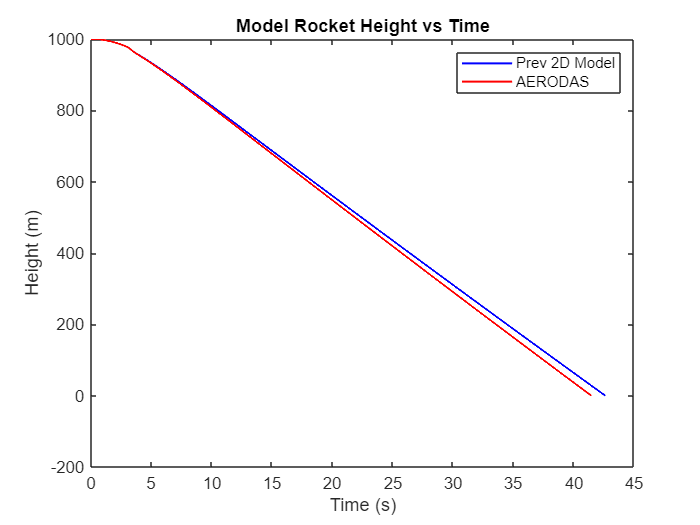

% Configurações de linha
lw = 1.2;

% Plot altura
figure(1)
plot(t1, h1, 'b', 'LineWidth', lw)
hold on
plot(t2, h2, 'r', 'LineWidth', lw)
title('Model Rocket Height vs Time')
xlabel('Time (s)')
ylabel('Height (m)')
legend('Prev 2D Model', 'AERODAS')

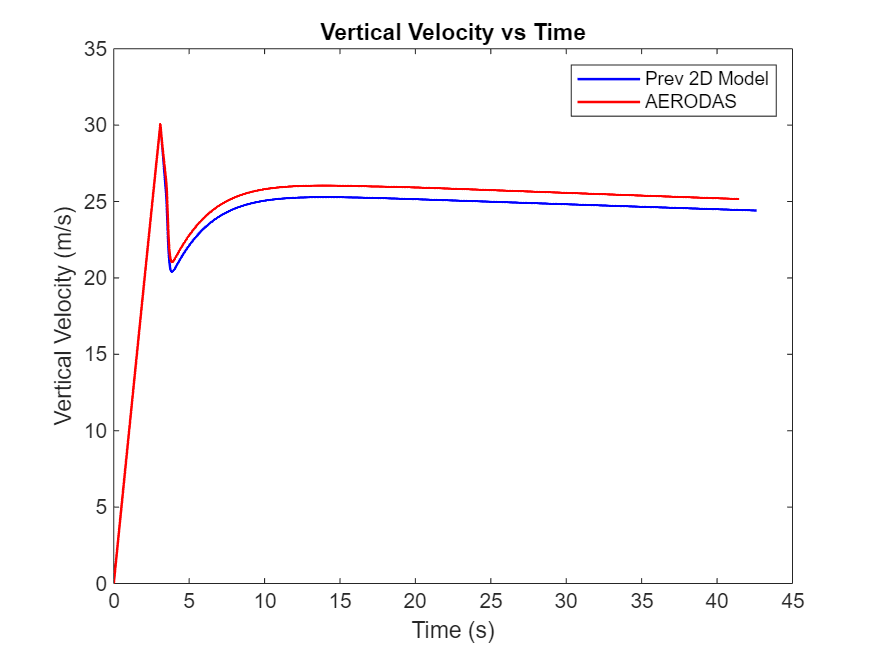

% Plot velocidade vertical
figure(2)
plot(t1, v1, 'b', 'LineWidth', lw)
hold on
plot(t2, v2, 'r', 'LineWidth', lw)
title('Vertical Velocity vs Time')
xlabel('Time (s)')
ylabel('Vertical Velocity (m/s)')
legend('Prev 2D Model', 'AERODAS')

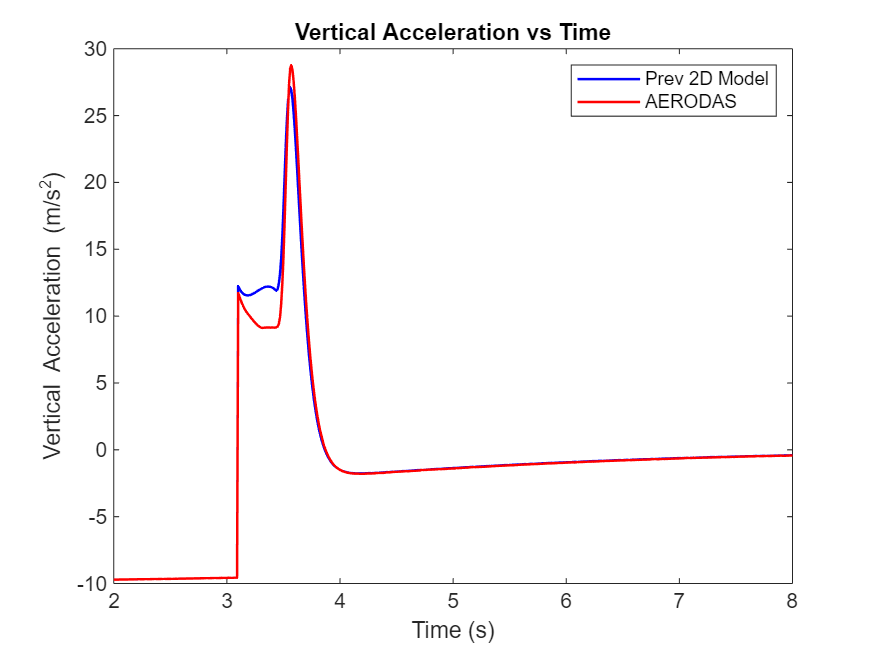

% Plot aceleração vertical
figure(3)
plot(t1, a1, 'b', 'LineWidth', lw)
hold on
plot(t2, a2, 'r', 'LineWidth', lw)
title('Vertical Acceleration vs Time')
xlabel('Time (s)')
ylabel('Vertical Acceleration (m/s^2)')
legend('Prev 2D Model', 'AERODAS')
xlim([2 8])

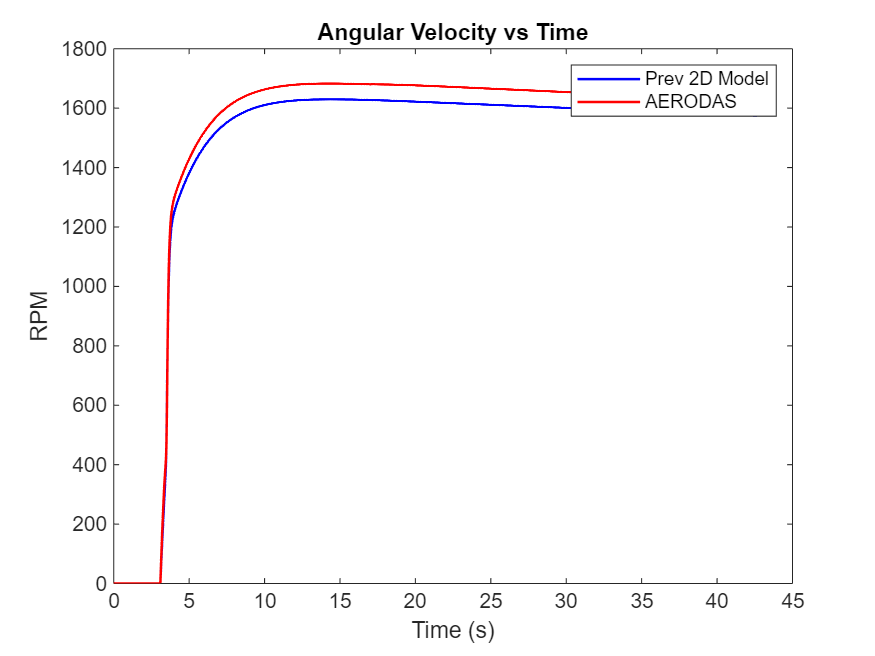

% Plot velocidade angular (RPM)
figure(4)
plot(t1, w1 * 60 / (2 * pi), 'b', 'LineWidth', lw)
hold on
plot(t2, w2 * 60 / (2 * pi), 'r', 'LineWidth', lw)
title('Angular Velocity vs Time')
xlabel('Time (s)')
ylabel('RPM')
legend('Prev 2D Model', 'AERODAS')

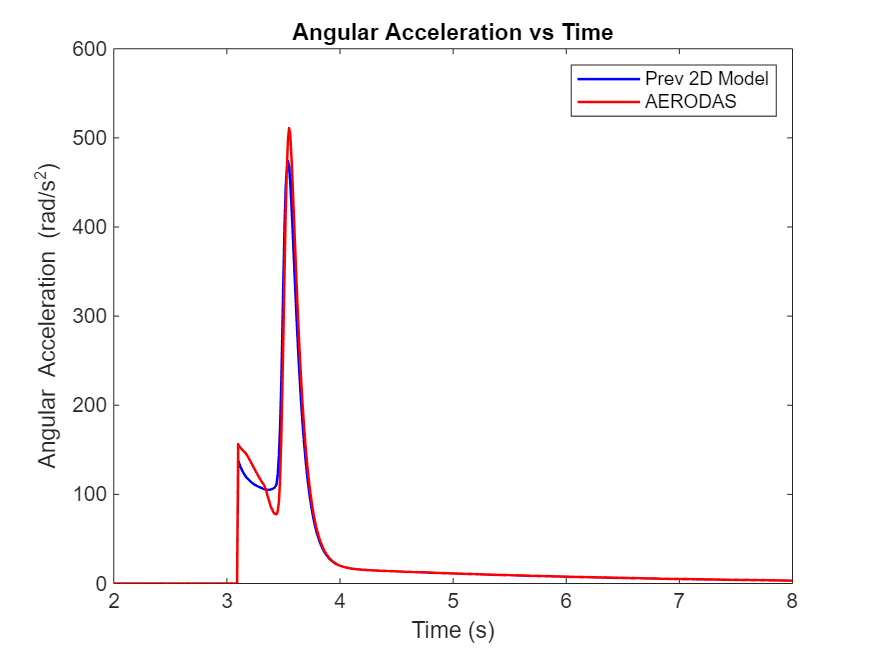

% Plot aceleração angular
figure(5)
plot(t1, a_ang1, 'b', 'LineWidth', lw)
hold on
plot(t2, a_ang2, 'r', 'LineWidth', lw)
title('Angular Acceleration vs Time')
xlabel('Time (s)')
ylabel('Angular Acceleration (rad/s^2)')
legend('Prev 2D Model', 'AERODAS')
xlim([2 8])

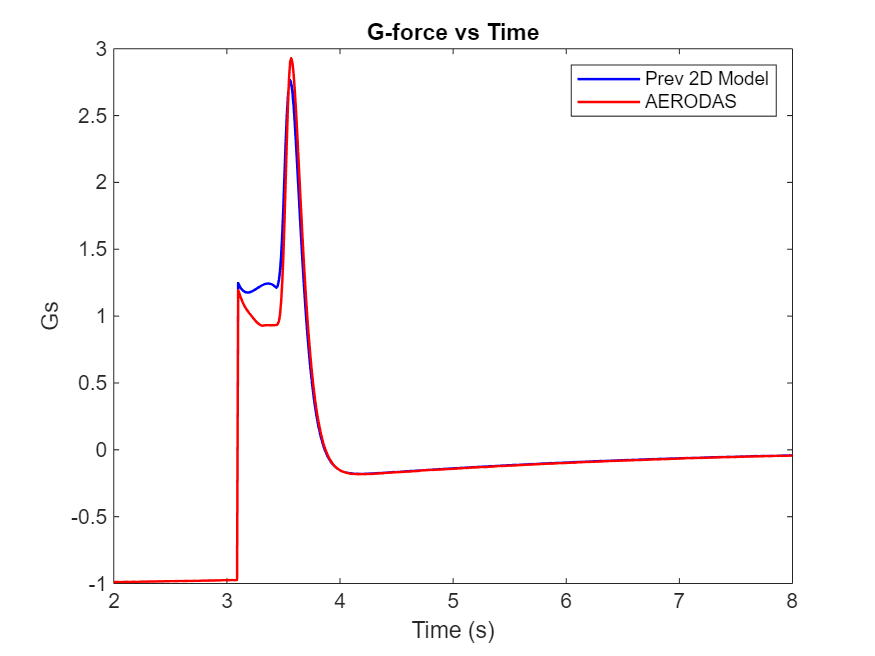

% Plot força G
figure(6)
plot(t1, g_force1, 'b', 'LineWidth', lw)
hold on
plot(t2, g_force2, 'r', 'LineWidth', lw)
title('G-force vs Time')
xlabel('Time (s)')
ylabel('Gs')
legend('Prev 2D Model', 'AERODAS')
xlim([2 8])

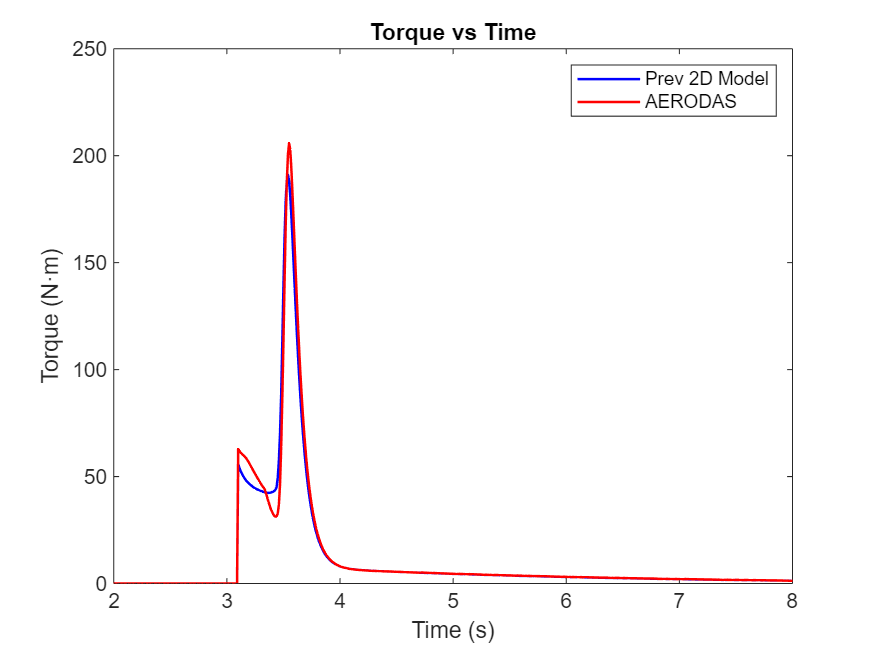

% Plot torque
figure(7)
plot(t1, torque1, 'b', 'LineWidth', lw)
hold on
plot(t2, torque2, 'r', 'LineWidth', lw)
title('Torque vs Time')
xlabel('Time (s)')
ylabel('Torque (N·m)')
legend('Prev 2D Model', 'AERODAS')
xlim([2 8])

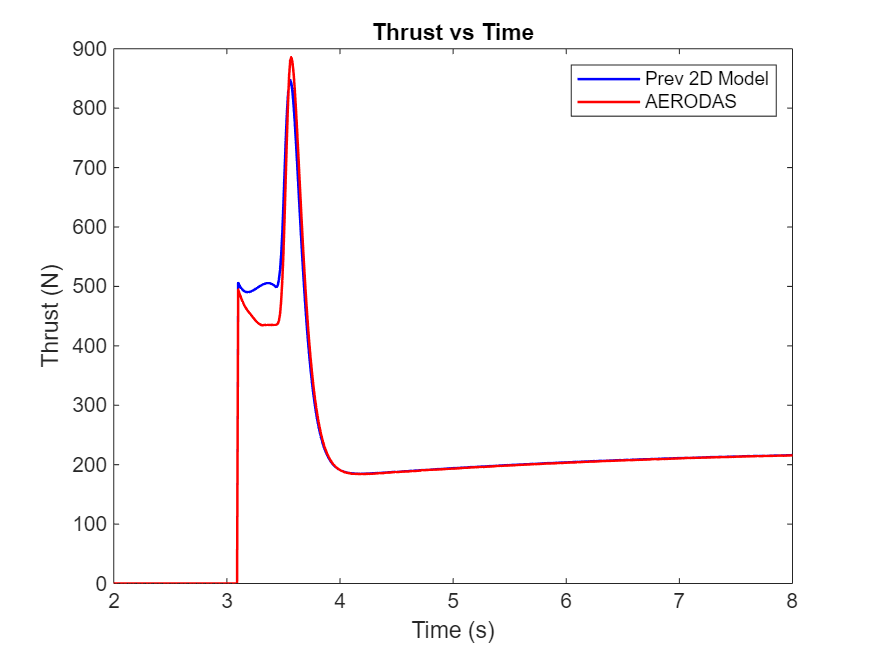

% Plot thrust
figure(8)
plot(t1, thrust1, 'b', 'LineWidth', lw)
hold on
plot(t2, thrust2, 'r', 'LineWidth', lw)
title('Thrust vs Time')
xlabel('Time (s)')
ylabel('Thrust (N)')
legend('Prev 2D Model', 'AERODAS')
xlim([2 8])

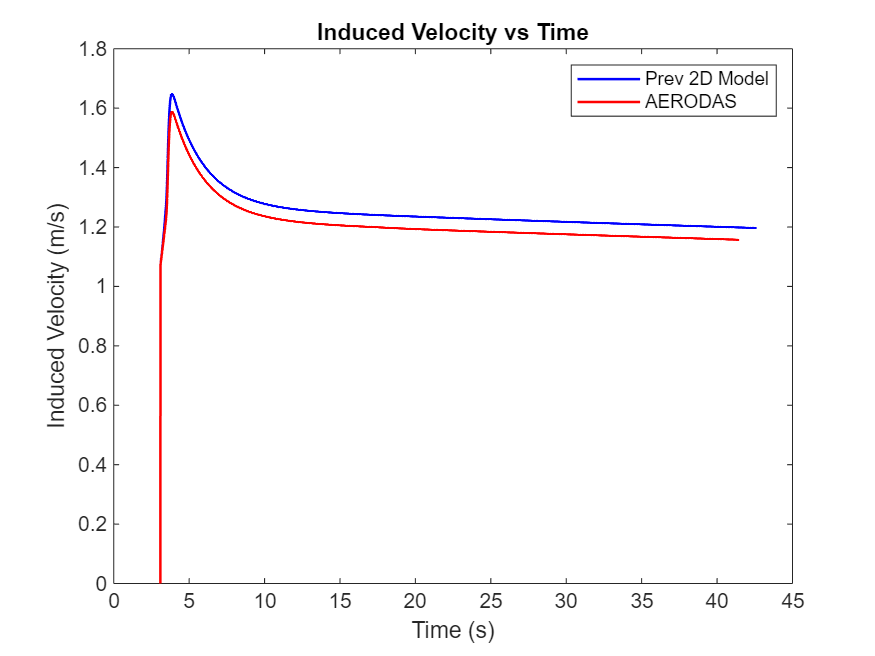


% Plot velocidade induzida
figure(9)
plot(tvi1, vi1, 'b', 'LineWidth', lw)
hold on
plot(tvi2, vi2, 'r', 'LineWidth', lw)
title('Induced Velocity vs Time')
xlabel('Time (s)')
ylabel('Induced Velocity (m/s)')
legend('Prev 2D Model', 'AERODAS')